# Functions

Anonymous functions

f = @(x) x.^2 + sin(3*x + 1)

f = function_handle with value:
    @(x)x.^2+sin(3*x+1)


Podemos calcular como normalmente hacemos sobre el papel. Tambien, si esta preparada para ello, podemos pasarle una lista.

f(2)

ans = 4.6570

f([1,2,3,4,5,6,7,8])

ans =     0.2432    4.6570    8.4560   16.4202   24.7121   36.1499   48.9911   63.8676


Podemos graficar la funcion normalmente (plot), o si esta es anonima (fplot dado el dominio):

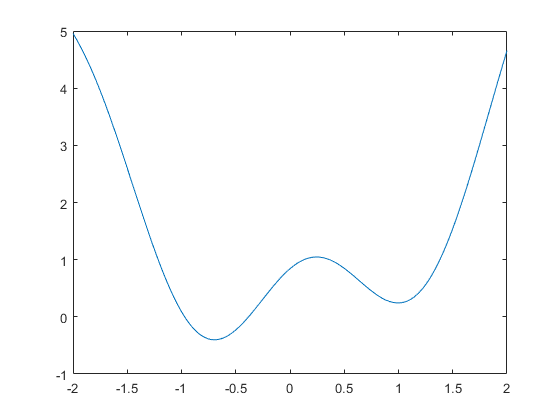

t = [-2: 0.01 :2];
plot(t,f(t))

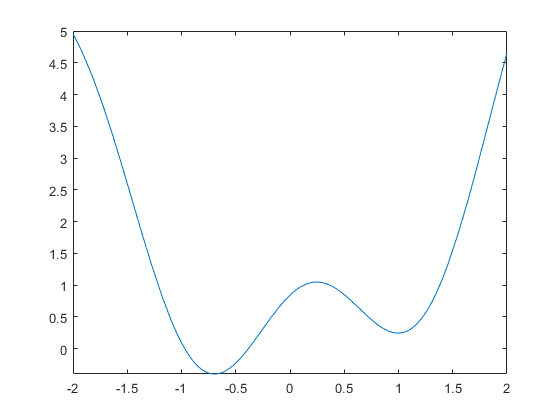

fplot(f,[-2,2])

Podemos hacerlas de mas de una variable:

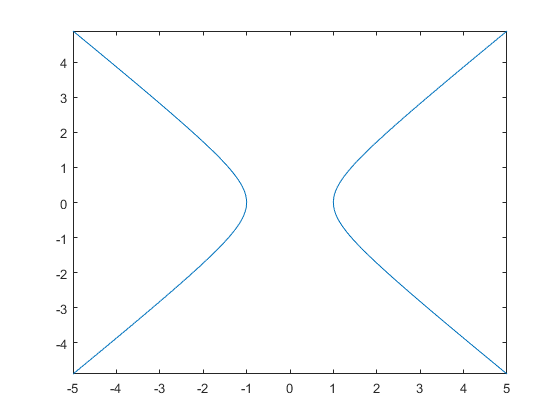

f = @(x,y) x.^2 - y.^2 - 1;
fimplicit(f)

function [d,x] = xifres(x,y)
[ea, er, ep] = funerror(x,y);
d = fix(-log10(2*ea));
x = fix(-log10(2*er));
end